I = imread('..\datasets\segmentation-evaluation-database\1obj\100_0109\src_color\100_0109.png');
%I = imread('..\datasets\segmentation-evaluation-database\1obj\100_0497\src_color\100_0497.png');

I = imresize(I, [50 NaN]);
[rows, cols, ~] = size(I);

X = image_transform(I);

hs = linspace(0.1, 3, 10);
v = zeros(length(hs), 1);
for i = 1:length(hs)
    v(i) = MLCV(hs(i), X);
end

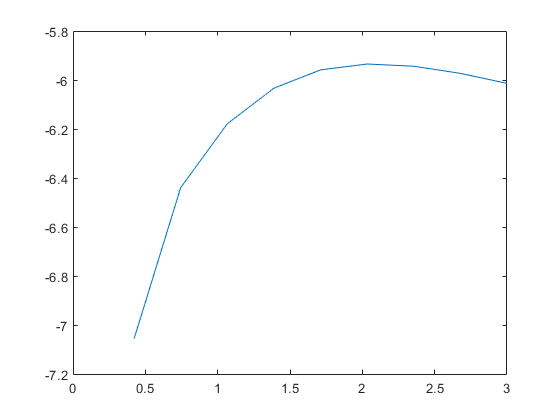

figure
plot(hs, v);

[~, max_i] = max(v);
h = hs(max_i);

[A, C, T] = mean_shift3(X, h, 0.1);
size(C, 2)

ans = 1

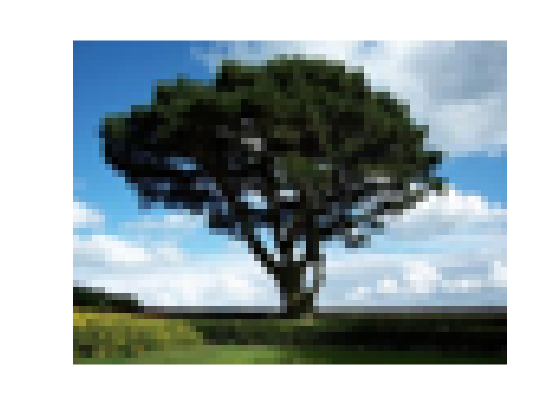

figure
imshow(I, [], 'InitialMagnification', 'fit');

figure
imshow(reshape(A, rows, cols), [], 'InitialMagnification', 'fit');

function result = MLCV(h, X)
    [d, n] = size(X);
    s = 0;
    for i=1:n
        w = exp(-0.5 * sum(((X(:,(1:n) ~= i) - X(:,i)) / h).^2, 1));
        s = s + log((2 * pi)^(-d/2) * sum(w));
    end
    result =  n^-1 * s - log((n-1) * h);
end